clear;
syms s;
f = ((s+8)*(s+6.9)*(s^2+s*7+15)*(1.5*s^2+8*s+30)*(s+12)*(s+2.1)*(0.5*s^2+9.5*s+47.01))/((s^2+1.6*s+1)*(s+10)*(s^2+6*s+12)*(s+5)*(s+2)*(s+7)*(0.5*s^2+9.5*s+47));
[n, d]=numden(f);
fdt=tf(sym2poly(n),sym2poly(d))


fdt =
 
   15000 s^10 + 905000 s^9 + 2.4e07 s^8 + 3.694e08 s^7 + 3.676e09 s^6 + 2.489e10 s^5 + 1.171e11 s^4 + 3.799e11 s^3 + 8.149e11 s^2 + 1.039e12 s + 5.885e11
  --------------------------------------------------------------------------------------------------------------------------------------------------------
  10000 s^10 + 506000 s^9 + 1.098e07 s^8 + 1.339e08 s^7 + 1.009e09 s^6 + 4.889e09 s^5 + 1.538e10 s^4 + 3.088e10 s^3 + 3.769e10 s^2 + 2.562e10 s + 7.896e09
 
Continuous-time transfer function.



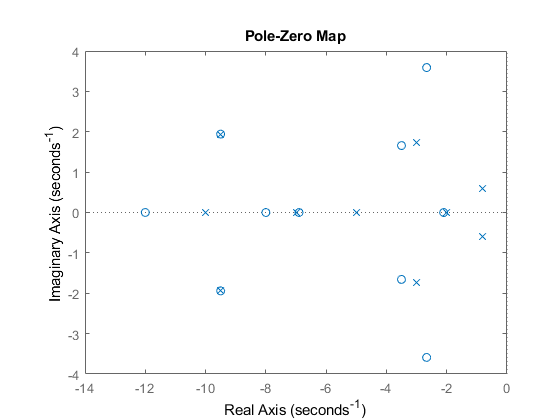

pzmap(fdt)

%Simplificamos
f_simplificada = ((s^2+s*7+15)*(1.5*s^2+8*s+30))/((s^2+1.6*s+1)*(s^2+6*s+12)*(s+5));

[n, d]=numden(f_simplificada);
fdt_simplificada=tf(sym2poly(n),sym2poly(d))


fdt_simplificada =
 
      15 s^4 + 185 s^3 + 1085 s^2 + 3300 s + 4500
  ----------------------------------------------------
  10 s^5 + 126 s^4 + 606 s^3 + 1382 s^2 + 1380 s + 600
 
Continuous-time transfer function.



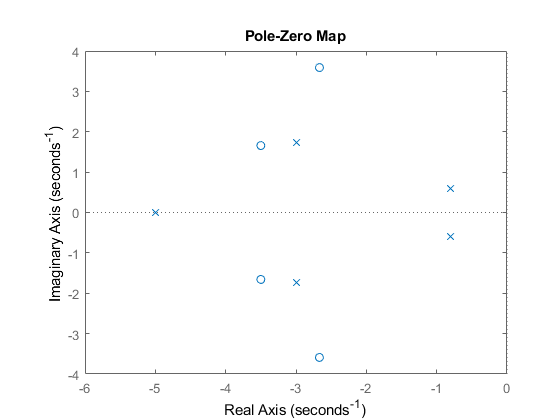

pzmap(fdt_simplificada)